# Damped Harmonic Motion

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

This activity will guide you through obtaining the solution matrix for the following system of first-order ODEs.

*d**y/d**t*=*v*

*d**v/d**t*=−*b/m v*−*k/m y*

where *m*=0.05 kg, *b*=0.5kg/s, and *k*=50 N/m.

The spring is initially stretched 0.1m away from its unstretched length and the block is released from rest at that position. 

tRange = [0 1];
Y0 = [0.1; 0];
[tSol, YSol] = ode45(@harmonicMotion, tRange, Y0);

## Task 2

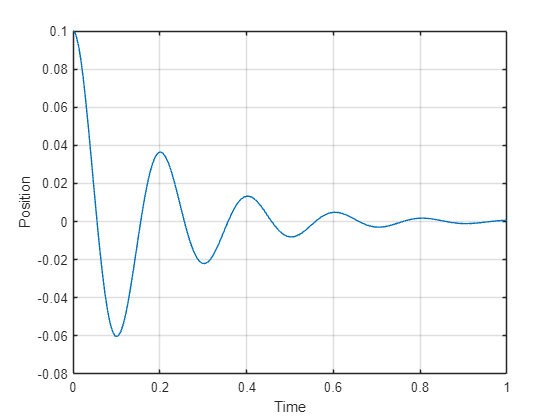

y = YSol(:, 1);
plot(tSol, y)
grid on
% Label axes
xlabel("Time")
ylabel("Position")

## Task 3

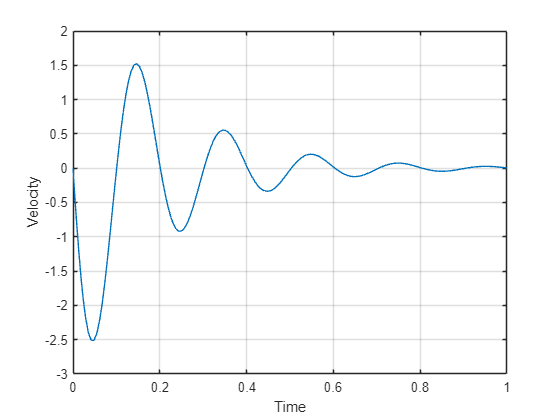

v = YSol(:, 2);
plot(tSol, v) 
grid on
% Label axes
xlabel("Time")
ylabel("Velocity")

## ODE function

Do not edit. This code defines the ODE function for the system of ODEs.

function dYdt = harmonicMotion(t, Y)
    %Define constants k, m, and b
    k = 50;
    m = 0.05;
    b = 0.5;
    
    % TODO - Extract the position x from the first element of Y.
    y = Y(1);
    
    % TODO - Extract the velocity v from the second element of Y.
    v = Y(2);
    
    % TODO - Complete expression for dxdt
    dxdt = v;
    
    % TODO - Complete expression for dvdt
    dvdt = -(k/m)*y - (b/m)*v;
    
    % TODO - Create dYdt, column vector containing dxdt, and dvdt
    dYdt = [dxdt; dvdt];
end